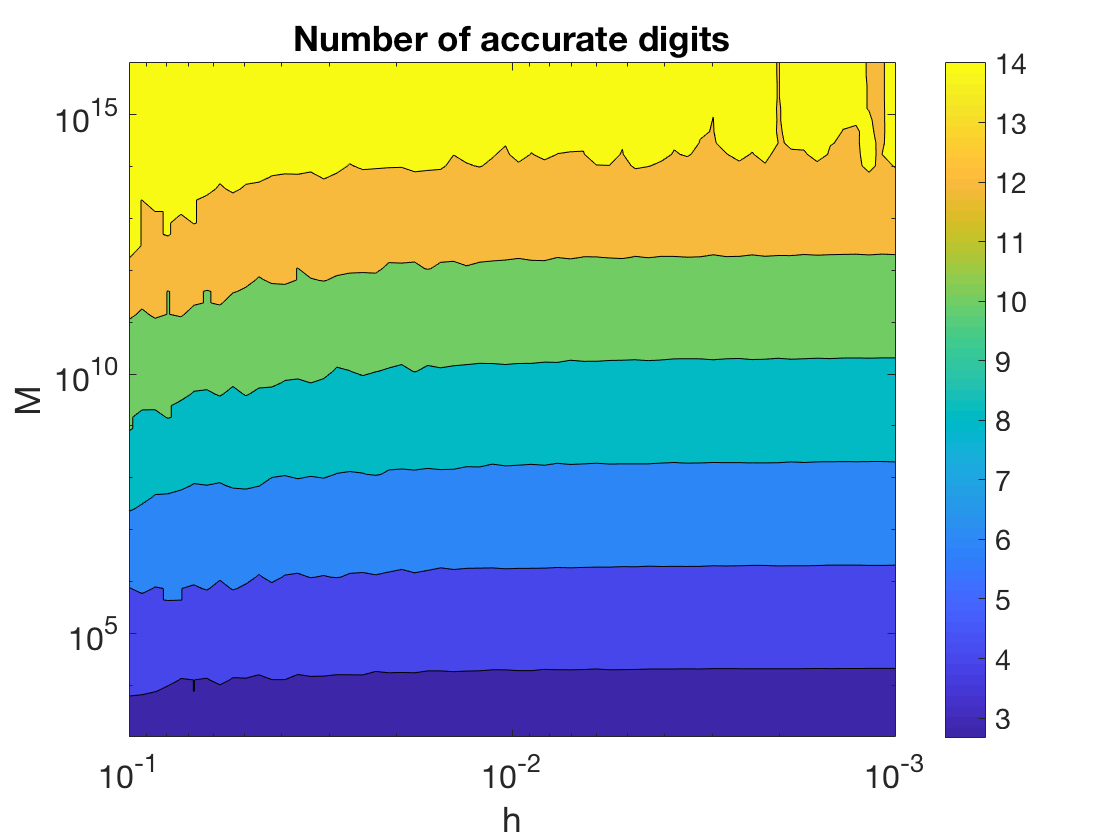

f = @(x) 1./(1+x.^2);
h = logspace(-3,-1,60);
M = logspace(3,16,60);

for i = 1:length(h)
    for j = 1:length(M)
        I(i,j) = intde(f,h(i),M(j));
    end
end
err = abs(I-pi);
contourf(h,M,-log10(err)')
set(gca,'xsc','log','xdir','rev','ysc','log') % ignore this line
colorbar   % ignore this line
xlabel('h'), ylabel('M')   % ignore this line
title('Number of accurate digits')  % ignore this line

As predicted, the error can't much beat $1/M$. Even for very large $M$, however, not many nodes are needed, as seen in the very weak dependence of the accuracy on $h$. For instance,

[I,x] = intde(f,0.1,1e10);
err = abs(pi-I)

err =      4.076738946423575e-12


number_of_nodes = length(x)

number_of_nodes =     71


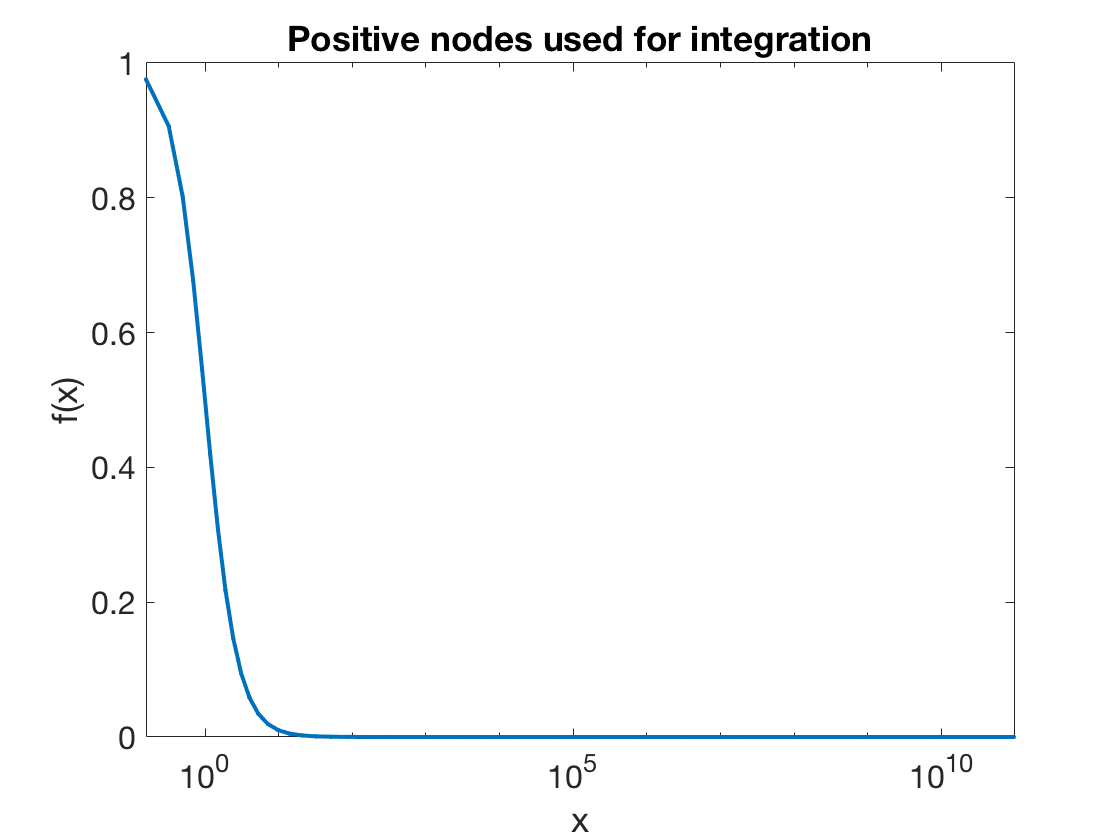


xpos = (x>0);
semilogx(x(xpos),f(x(xpos)),'.-')
axis tight, ylim([0 1])   % ignore this line
xlabel('x'), ylabel('f(x)')   % ignore this line
title('Positive nodes used for integration')   % ignore this line